# II projektni zadatak iz robotike Lazar Stojanović 203/17 i Filip Bakić 161/17

global m1 m2 I1 I2 l1 l2 ls g Fint Tau l

t = 0;          % inicijalizacija vremena [s]
dt = 0.001;     % korak simulacije [s]
i = 1;          % brojac
g = 9.81;       % g
Fint = [2; 1];  % spoljasnja sila [N]


Pocetno stanje

q = [90*pi/180; 0*pi/180]; % pozicija
dq = [0; 0];                % brzina
ddq = [0; 0];               % ubrzanje


Parametri segmenata

l1 = 0.5;       % [m] duzina segmenta 1
l2 = 0.5;  % [m] duzina segmenta 2
ls= 0.1;
m1 = 2;         % [kg] masa segmenta 1
m2 = 3;         % [kg] masa segmenta 2
I1 = m1*l1^2/3;      % [kgm^2] moment inercije segmenta 1
I2 = m2*l2;      % [kgm^2] moment inercije segmenta 1
l = l1;

# Planiranje trajektorije 

U zavisnosti na zadata maksimalna ubrzanja racunamo vrednosti za trapezni model brzine i biramo maksimum:


$$Ta=\frac{\dot{q}_{max}}{\ddot{q}_{max}}$$
 
$$T_f=\frac{\Delta q}{\dot{q}_{max}}$$
 

A_poc = [90*pi/180; 0*pi/180];
A_kraj = [60*pi/180; -75*pi/180];
ddqa_max = 10;
dqa_max = 0.1;

Taa = dqa_max/ddqa_max;
Tfa = Taa + max(abs(A_poc-A_kraj))/dqa_max;

ddq1_max = (A_kraj(1) - A_poc(1))/(Taa * (Tfa - Taa));
ddq2_max = (A_kraj(2) - A_poc(2))/(Taa * (Tfa - Taa));
ddq_a_max = [ddq1_max; ddq2_max];


A za polinom 5. stepena racunamo vreme trajanja iz formula izvedenih na vežbama i biramo maksimum između zglobova

B_poc = [60*pi/180; -75*pi/180];
B_kraj = [45*pi/180; -45*pi/180];

ddqb_max = 7;

dqb_max = 0.05;
dp_max = 15/8;

ddp_max = 10*sqrt(3)/3;
T1 = abs(B_kraj - B_poc)/dqb_max * dp_max;
T2 = sqrt(abs(B_kraj - B_poc)/ddqb_max * ddp_max);
Tfb = max(max([T1 T2]));
Tb_poc=Tfa;
T=Tfa+Tfb;

Prema izračunatim trajanjima $T_{fA} 
$ i $T_{fB}

$ generišemo trajektoriju

vreme = length(0:dt:T);
ddq_ref = zeros(2,vreme);
dq_ref = zeros(2,vreme);
q_ref = zeros(2,vreme);

for i = 1:vreme
 % generisanje trapezne trajektorije   
    if i <= floor(Taa/dt) 
        ddq_ref(:,i) = ddq_a_max;
        dq_ref(:,i) = ddq_ref(:,i)*(i-1)*dt;
       q_ref(:,i) = A_poc + 0.5*ddq_ref(:,i)*((i-1)*dt)^2;
    end
    
    if i > floor(Taa/dt) && i <= floor((Tfa-Taa)/dt) 
        ddq_ref(:,i) = 0;
        dq_ref(:,i) = ddq_a_max * Taa;
        q_ref(:,i) = A_poc + ddq_a_max*Taa*((i-1)*dt-0.5*Taa);
    end
    
    if i > floor((Tfa - Taa)/dt) && i <= floor(Tfa/dt) 
        ddq_ref(:,i) = -ddq_a_max;
        dq_ref(:,i) = ddq_a_max*(Tfa-(i)*dt);
        q_ref(:,i) = A_kraj - 0.5*ddq_ref(:,i)*(Tfa-(i-1)*dt)^2;
    end
	
	
	if i>floor(Tfa/dt) && i<=floor(Tb_poc/dt)
        ddq_ref(:,i) = 0;
        dq_ref(:,i) = 0;
        q_ref(:,i) = q_ref(:,i-1);
    end
    % trajektorija 5. stepena
    if i > Tb_poc/dt && i <= T/dt+1 
        t1 = ((i - 1)*dt - Tb_poc)/Tfb;    
        p = 6*t1^5 - 15*t1^4 + 10*t1^3;
        dp = 30*t1^4 - 60*t1^3 + 30*t1^2;
        ddp = 120*t1^3 - 180*t1^2 + 60*t1;
        ddq_ref(:, i) = (B_kraj - B_poc)/Tfb^2 * ddp;
        dq_ref(:, i) = (B_kraj - B_poc)/Tfb * dp;
        q_ref(:, i) = B_poc + (B_kraj - B_poc)*p;
    end    
end
q1_ref=q_ref(1,:);
q2_ref=q_ref(2,:);
dq1_ref=dq_ref(1,:);
dq2_ref=dq_ref(2,:);
ddq1_ref=ddq_ref(1,:);
ddq2_ref=ddq_ref(2,:);

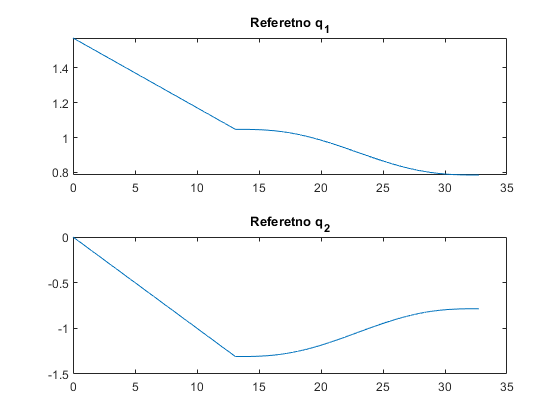

figure;

subplot(2,1,1)
plot(0:dt:T,q1_ref)
title('Referetno q_1')
subplot(2,1,2)
plot(0:dt:T,q2_ref)
title('Referetno q_2')

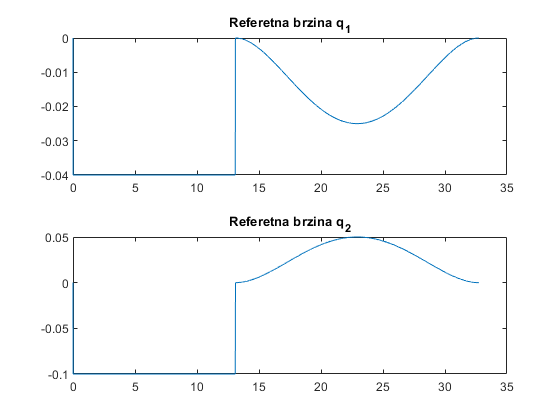


figure;
subplot(2,1,1)
plot(0:dt:T,dq1_ref)
title('Referetna brzina q_1')
subplot(2,1,2)
plot(0:dt:T,dq2_ref)
title('Referetna brzina q_2')


% figure;
% subplot(2,1,1)
% plot(0:dt:T,ddq1_ref)
% subplot(2,1,2)
% plot(0:dt:T,ddq2_ref)

# Simulacija

Za svaku iteraciju petlje $\Delta t = 0.001
$ racunamo matrice dinamike $H, C,G$ prema planiranoj i osvarenoj trajektoriji računamo $\tau$ sa pogrešno procenjenom matricom $\hat C =C/2$ ,a onda radimo kompenzaciju eksterne sile.Simuliramo robota pomoću numeričke integracije.

Kp1 = [700;700];       
Kd1 = [70;70];

R = eye(3);
W = [0 0 0;0 0 -0.1;0 0.1 0];
Tt = [R zeros(3) ; W * R R];

i=1;
t=dt;
Q = zeros(2,floor(T/dt));
dQ = zeros(2,floor(T/dt));
ddQ = zeros(2,floor(T/dt));
Tauu = zeros(2,floor(T/dt));
Tauufb = zeros(2,floor(T/dt));
Tauuff = zeros(2,floor(T/dt));
Xd = zeros(2,floor(T/dt));
Xdref = zeros(2,floor(T/dt));
dXd = zeros(2,floor(T/dt));
dXdref = zeros(2,floor(T/dt));
Q(:,1) = q;
dQ(:,1) = dq;
ddQ(:,1) = ddq;


while(t<T)
   t = i*dt;
       
   if t>0.7*T & t<0.8*T
   F=Fint;
   else
       F=zeros(2,1);
   end
   
   J = matrix_kin(q);
   J_ref = matrix_kin(q_ref(:,i));
   
   [X_ref, dX_ref] = forward_k(q_ref(:,i),dq_ref(:,i),J_ref);
   [X, dX] = forward_k(q,dq,J);
   
   [H,C,G]=matrix_d(q,dq);
   
   [Tau, Tau_FF, Tau_FB] = kontroler(q,q_ref(:,i),dq,dq_ref(:,i),ddq,ddq_ref(:,i),Kp1,Kd1,H,C/2,G,F,Tt,J);
   
   F_ext = Tt * [-F(1);-F(2); zeros(4,1)];

     
   
   Q_4 = [q; dq];
   options = odeset('RelTol',1e-2,'AbsTol',1e-3,'MaxOrder',3);
   [tout,Q_4_out] = ode45(@(t,Q_4) int_2DoF(t,Q_4,J,F_ext(1:2)),[t t+dt], Q_4, options);
   Q_4 = Q_4_out(end,:)';
   q = Q_4(1:2);
   dq = Q_4(3:4);
   ddq=H^-1*(Tau  - C*[dq(1); dq(2)]-G);
   
   i=i+1;
   Q(:,i) = q;
   dQ(:,i) = dq;
   ddQ(:,i) = ddq;
   Tauu(:,i) = Tau;
   Tauufb(:,i) = Tau_FB;
   Tauuff(:,i) = Tau_FF;
   Xd(:,i) = X;
   Xdref(:,i) = X_ref;
   dXd(:,i) = dX;
   dXdref(:,i) = dX_ref;
    end

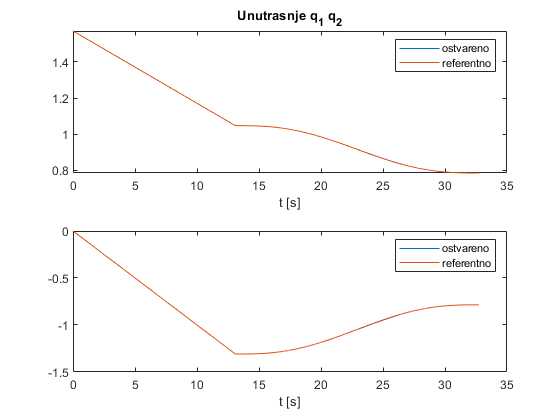

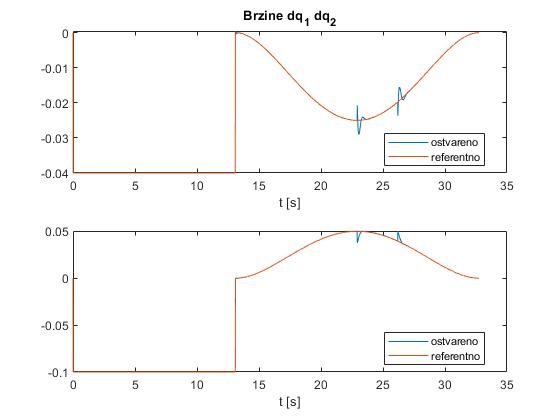

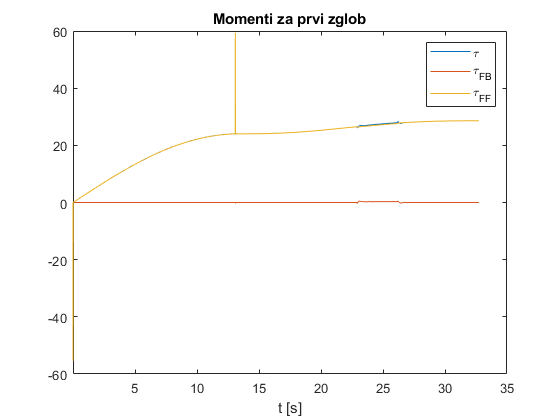

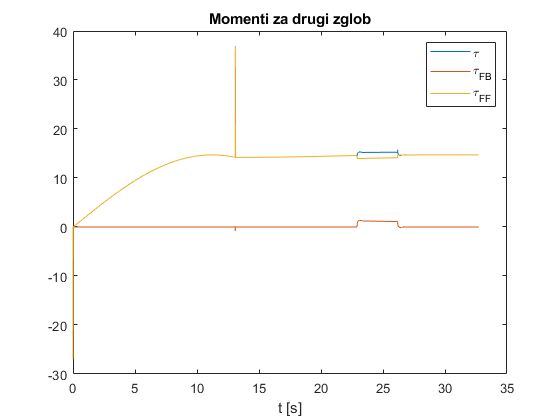

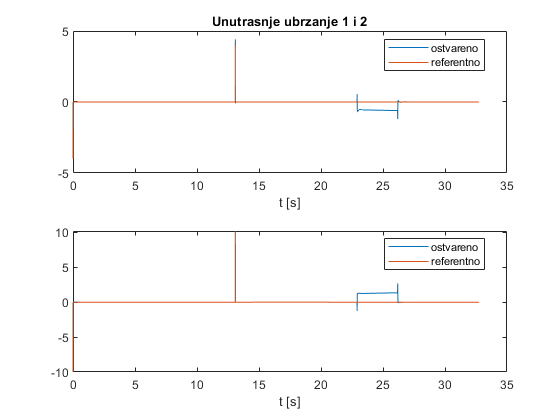

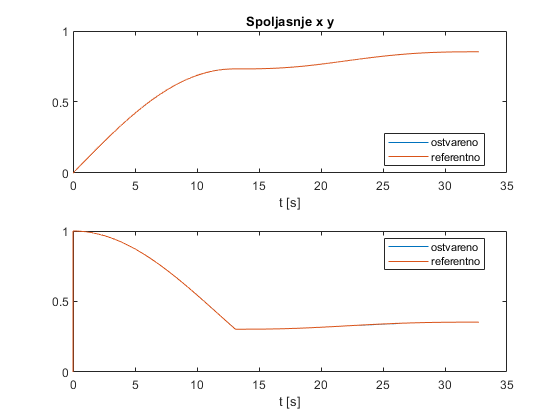

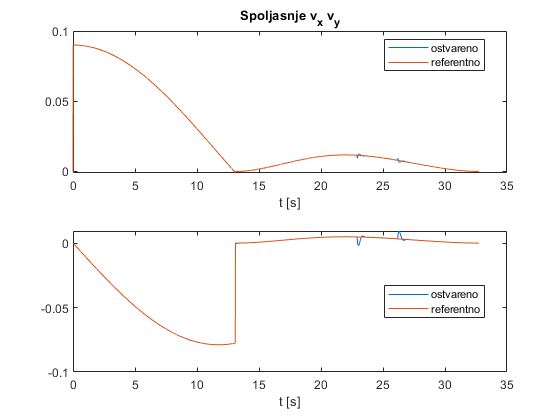

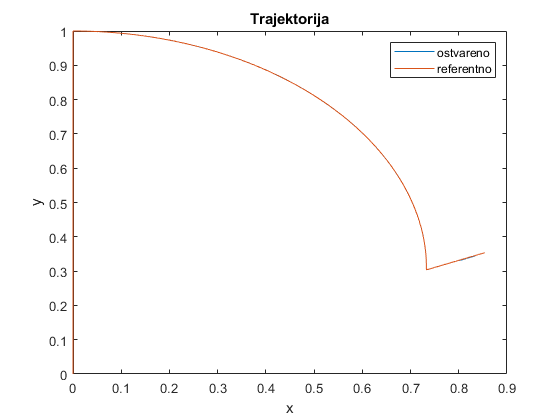

crtanje;